# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

Since we deal with a discrete-time implementation of controllers, we need to specify the sampling time. For this reason we select a choice of T on wich we are going to test our controllers.

T = [0.001 0.01 0.05];

## 2.1 Design by emulation

The discretization problem consists of finding a discrete-time controller C(z) such that the input–output transfer function of the sampled–data controller, approximates (in some sense) the transfer function C0(s).

### **2.1.1 Position PID Controller**

**TO BE IMPLEMENTED**

### **2.1.2 Position State-Space Controller**

Reconsider the position state–space controller for nominal and robust perfect tracking of constant set–points designed in the second laboratory activity. Differently from the second laboratory activity, suppose that the plant state is not fully accessible, so that a state observer is required to get an estimate of all the unmeasurable state variables.

**Reduced order state observer (CT)**

redObs.L = 100;
redObs.A0 = -(1/paramP.Tm + redObs.L);
redObs.B0 = [paramP.km/(gbox.N*paramP.Tm), -(1/paramP.Tm + redObs.L)*redObs.L];
redObs.C0 = [0; 1];
redObs.D0 = [0 1; 0 redObs.L];

**CT Test - Nominal tracking**

simul.stepdeg = 40;
nominal_track.CT.deg_40 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 70;
nominal_track.CT.deg_70 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
nominal_track.CT.deg_120 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

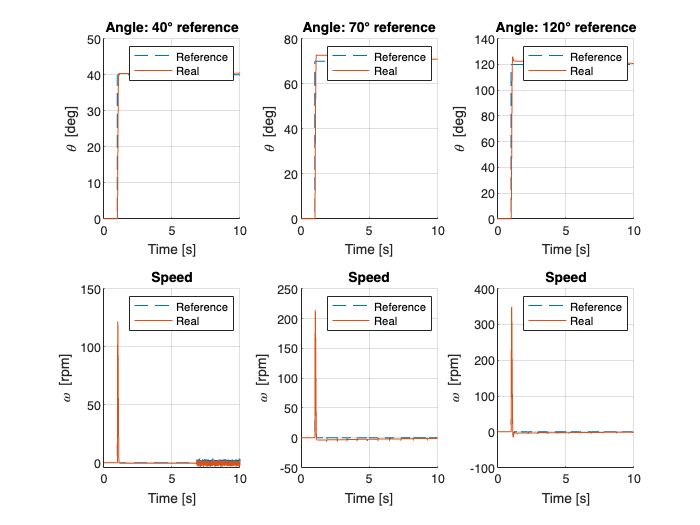

figure
subplot(2,3,1);
hold on;
plot(nominal_track.CT.deg_40.thref.time, nominal_track.CT.deg_40.thref.signals.values,'--');
plot(nominal_track.CT.deg_40.thl_meas.time, nominal_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.CT.deg_70.thref.time, nominal_track.CT.deg_70.thref.signals.values,'--');
plot(nominal_track.CT.deg_70.thl_meas.time, nominal_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.CT.deg_120.thref.time, nominal_track.CT.deg_120.thref.signals.values,'--');
plot(nominal_track.CT.deg_120.thl_meas.time, nominal_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.CT.deg_40.wl_meas.time, nominal_track.CT.deg_40.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_40.wl_est.time, nominal_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.CT.deg_70.wl_meas.time, nominal_track.CT.deg_70.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_70.wl_est.time, nominal_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.CT.deg_120.wl_meas.time, nominal_track.CT.deg_120.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_120.wl_est.time, nominal_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forwar Euler discretization**

We can repeat the same procedure also for other discretization methods. Pay attention to the simulation time T!! We perform the test of the controller using different sampling times

simul.stepdeg = 50;

Simulation for 1 ms

redObs.Ph0 = 1+ redObs.A0*T(1);
redObs.Gamma0 = redObs.B0*T(1);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

redObs.Ph0 = 1+ redObs.A0*T(2);
redObs.Gamma0 = redObs.B0*T(2);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

redObs.Ph0 = 1+ redObs.A0*T(3);
redObs.Gamma0 = redObs.B0*T(3);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

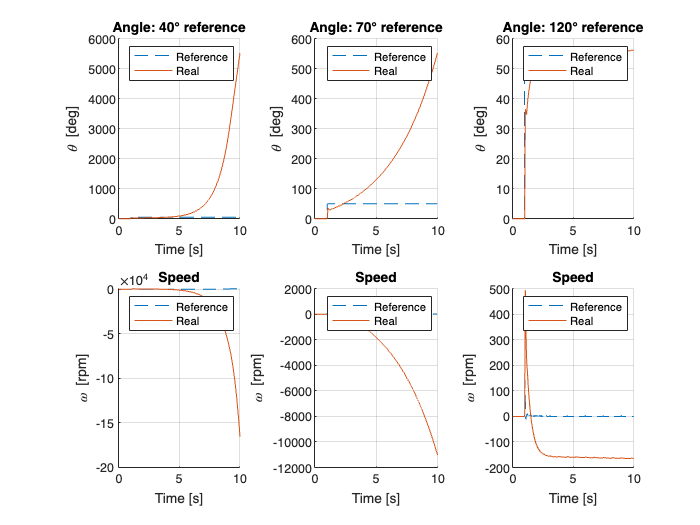

figure
subplot(2,3,1);
hold on;
plot(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--');
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.FE.T2.thref.time, nominal_track.FE.T2.thref.signals.values,'--');
plot(nominal_track.FE.T2.thl_meas.time, nominal_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--');
plot(nominal_track.FE.T3.thl_meas.time, nominal_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.FE.T1.wl_meas.time, nominal_track.FE.T1.wl_meas.signals.values,'--');
plot(nominal_track.FE.T1.wl_est.time, nominal_track.FE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.FE.T2.wl_meas.time, nominal_track.FE.T2.wl_meas.signals.values,'--');
plot(nominal_track.FE.T2.wl_est.time, nominal_track.FE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.FE.T3.wl_meas.time, nominal_track.FE.T3.wl_meas.signals.values,'--');
plot(nominal_track.FE.T3.wl_est.time, nominal_track.FE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

There might be some problem.

After this ction we can implement other discretizayions methods.

**Backward Euler discretization**

simul.stepdeg = 50;

Simulation for 1 ms

redObs.Ph0 = inv(1 - redObs.A0*T(1));
redObs.Gamma0 = inv(1 - redObs.A0*T(1))*redObs.B0*T(1);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(1));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(1))*redObs.B0*T(1);

nominal_track.BE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

redObs.Ph0 = inv(1 - redObs.A0*T(2));
redObs.Gamma0 = inv(1 - redObs.A0*T(2))*redObs.B0*T(2);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(2));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(2))*redObs.B0*T(2);

nominal_track.BE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

redObs.Ph0 = inv(1 - redObs.A0*T(3));
redObs.Gamma0 = inv(1 - redObs.A0*T(3))*redObs.B0*T(3);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(3));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(3))*redObs.B0*T(3);

nominal_track.BE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

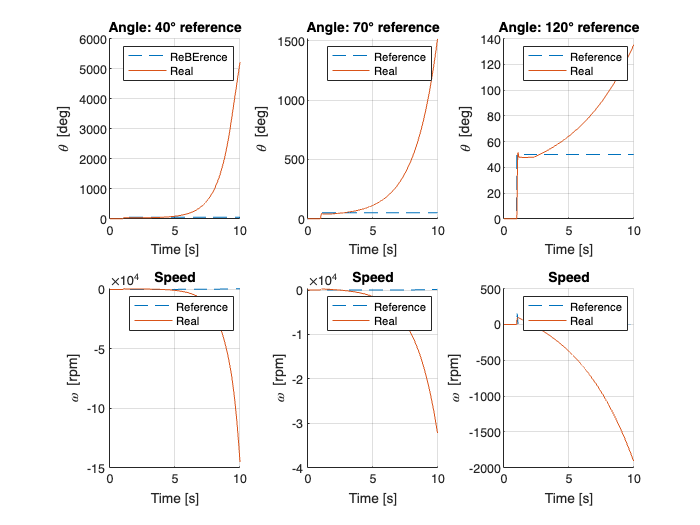

figure
subplot(2,3,1);
hold on;
plot(nominal_track.BE.T1.thref.time, nominal_track.BE.T1.thref.signals.values,'--');
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values);
legend('ReBErence', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.BE.T2.thref.time, nominal_track.BE.T2.thref.signals.values,'--');
plot(nominal_track.BE.T2.thl_meas.time, nominal_track.BE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--');
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.BE.T1.wl_meas.time, nominal_track.BE.T1.wl_meas.signals.values,'--');
plot(nominal_track.BE.T1.wl_est.time, nominal_track.BE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.BE.T2.wl_meas.time, nominal_track.BE.T2.wl_meas.signals.values,'--');
plot(nominal_track.BE.T2.wl_est.time, nominal_track.BE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.BE.T3.wl_meas.time, nominal_track.BE.T3.wl_meas.signals.values,'--');
plot(nominal_track.BE.T3.wl_est.time, nominal_track.BE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

save('NominalTrack.mat','nominal_track');

**CT - Robust tracking**

We have already implemeted the observer. we have just to put in the model and to test it

simul.stepdeg = 40;
robust_track.CT.deg_40 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 70;
robust_track.CT.deg_70 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
robust_track.CT.deg_120 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

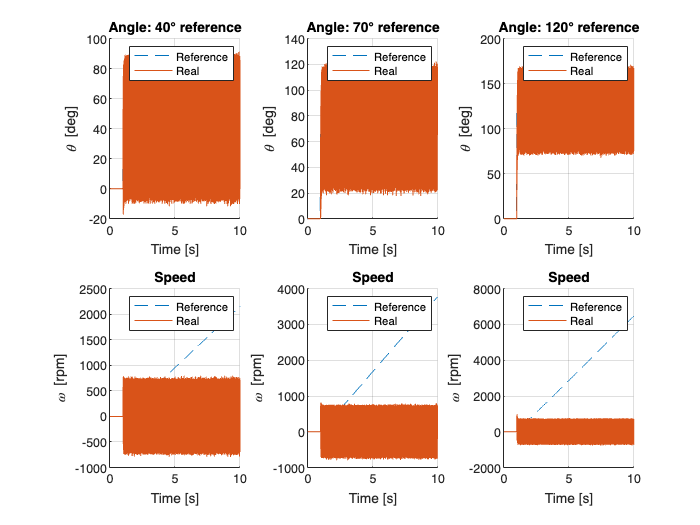

figure
subplot(2,3,1);
hold on;
plot(robust_track.CT.deg_40.thref.time, robust_track.CT.deg_40.thref.signals.values,'--');
plot(robust_track.CT.deg_40.thl_meas.time, robust_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(robust_track.CT.deg_70.thref.time, robust_track.CT.deg_70.thref.signals.values,'--');
plot(robust_track.CT.deg_70.thl_meas.time, robust_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(robust_track.CT.deg_120.thref.time, robust_track.CT.deg_120.thref.signals.values,'--');
plot(robust_track.CT.deg_120.thl_meas.time, robust_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')

subplot(2,3,4)
hold on;
plot(robust_track.CT.deg_40.wl_meas.time, robust_track.CT.deg_40.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_40.wl_est.time, robust_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,5)
hold on;
plot(robust_track.CT.deg_70.wl_meas.time, robust_track.CT.deg_70.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_70.wl_est.time, robust_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,6)
hold on;
plot(robust_track.CT.deg_120.wl_meas.time, robust_track.CT.deg_120.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_120.wl_est.time, robust_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forwar Euler discretization**

simul.stepdeg = 50;

Simulation for 1 ms

redObs.Ph0 = 1+ redObs.A0*T(1);
redObs.Gamma0 = redObs.B0*T(1);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T1 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

redObs.Ph0 = 1+ redObs.A0*T(2);
redObs.Gamma0 = redObs.B0*T(2);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T2 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

redObs.Ph0 = 1+ redObs.A0*T(3);
redObs.Gamma0 = redObs.B0*T(3);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T3 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

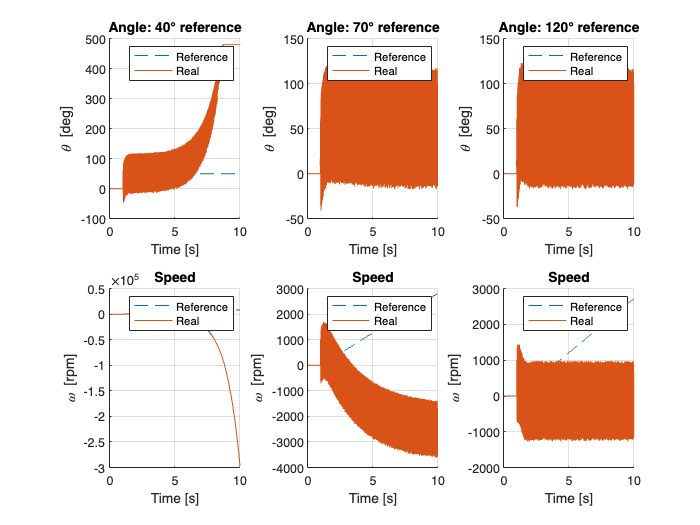

figure
subplot(2,3,1);
hold on;
plot(robust_track.FE.T1.thref.time, robust_track.FE.T1.thref.signals.values,'--');
plot(robust_track.FE.T1.thl_meas.time, robust_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(robust_track.FE.T2.thref.time, robust_track.FE.T2.thref.signals.values,'--');
plot(robust_track.FE.T2.thl_meas.time, robust_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(robust_track.FE.T3.thref.time, robust_track.FE.T3.thref.signals.values,'--');
plot(robust_track.FE.T3.thl_meas.time, robust_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(robust_track.FE.T1.wl_meas.time, robust_track.FE.T1.wl_meas.signals.values,'--');
plot(robust_track.FE.T1.wl_est.time, robust_track.FE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(robust_track.FE.T2.wl_meas.time, robust_track.FE.T2.wl_meas.signals.values,'--');
plot(robust_track.FE.T2.wl_est.time, robust_track.FE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(robust_track.FE.T3.wl_meas.time, robust_track.FE.T3.wl_meas.signals.values,'--');
plot(robust_track.FE.T3.wl_est.time, robust_track.FE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

## **2.2 **Direct digital desing

The direct design in the discrete–time domain can be performed with any of the available classical or modern design methods, after having obtained a discrete–time model of the plant to be controlled with the exact discretization method.

#### Discretization of the model

Discretise the continuous–time state–space model Σ = (A, B, C, D) of the DC gearmotor using the exact method, to obtain the “ZOH discrete equivalent” Σd = (Φ, Γ, H, J). Note that since D = 0, then also J = 0. This condition will be considered throughout all this section.The discretization can be performed by using the c2d routine of the Control System Toolbox (CST), making sure to specify ’zoh’ as the discretization method.

#### Nominal perfect tracking

Design a discrete–time position state–space controller for nominal perfect tracking of constant position set–points, using the discretised plant model Σd obtained in point 1.Since the motor speed is not directly measurable, consider to design a discrete–time reduced– order observer for estimating it. The speed estimate, together with the motor position provided by the encoder, will be used to perform the state feedback.

#### **Robust perfect tracking**

Design a discrete–time position state–space controller with integral action to achieve robust perfect tracking of constant position set–points, and perfect rejection of constant turbances. For the design, use the discretised plant model Σd obtained in point discrete–time reduced–order observer similar to that obtained in point 2.